# Proyecto Final: Moviles y Gravedad Sol Tierra y Venus

## **Algoritmos Numéricos por Computadora**

## Manuel Fernández 166496

## Bernardo Altamirano 167881

## Santiago Borobia 165323

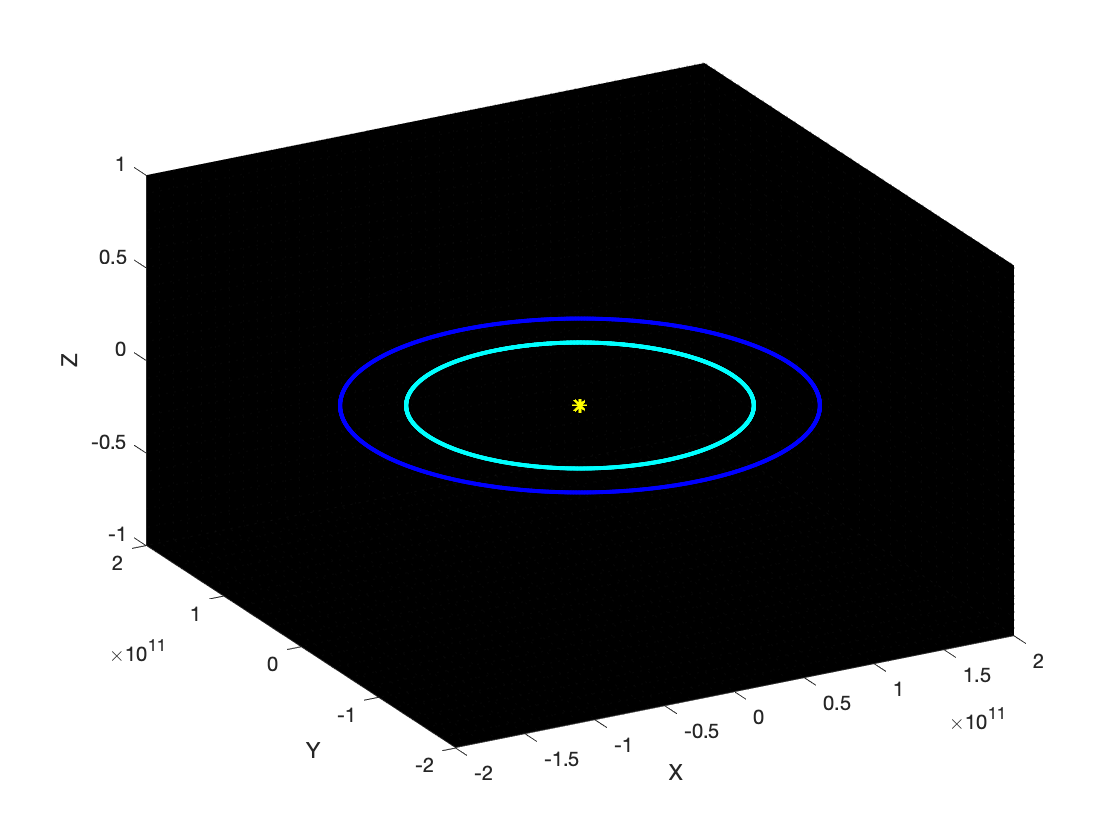

% Un satélite orbitando la Tierra
% La Tierra en el origen (inicialmente)
% El satélite tiene una masa de 20 toneladas 
% y se encuentra a 108 km de altura (eje x)
% Los vectores tienen los datos [Tierra, satélite]
  
% y  = [r;v] 
% y' = [v;a]
% dy/dt = f(t,y)

global G m;
G = 6.67408E-11;              % m3 kg-1 s-2
mS = 1.989e30;                % masa de Sol
mV = 4.867e24;                % masa de Venus
mT = 5.9736e24;               % masa de Tierra
m = [mS, mV, mT]; 

rS = 695.510e6;                     % radio del Sol m
hV = 108.2e9;                       % altura de la superficie del Sol a Venus        
hT = 149.6e9;                       % altura de la superficie del Sol a la Tierra

r0 = [ [0;0;0], [rS+hV;0;0], [rS+hT;0;0] ];      
                                    
vV = sqrt(G * m(1)/r0(1,2));
vT = sqrt(G * m(1)/r0(1,3));
v0 = [ [0;0;0], [0;vV;0], [0;vT;0] ];         

wV = vV/(rS+hV);
wT = vT/(rS+hT);

TV = (2*pi)/wV;  
TT = (2*pi)/wT; 

h = 60000;                 
nv = 2;                 
NkV = nv*ceil(TV/h);
NkT = nv*ceil(TT/h); 

pos = zeros(9,NkT+1);    
pos(:,1) = [r0(:,1);r0(:,2);r0(:,3)];

%Esto es un rk4 
y1 = [r0;v0];
pos = rk4(@f1, NkT, y1, pos, h);

hold on;
plot3(pos(1,:),pos(2,:),pos(3,:),'*y');
plot3(pos(4,:),pos(5,:),pos(6,:),'.c');
plot3(pos(7,:),pos(8,:),pos(9,:),'.b');
grid minor;
xlabel('X');
ylabel('Y');
zlabel('Z');
view([-29 32]);
set(gca,'Color','k');

function ydot = f1(~,y)
  global G m;                 
  r = y(1:3,:);
  v = y(4:6,:);
  
  drA = r(:,2) - r(:,1);         %Sol vs Venus
  uA = drA / norm(drA);            
  drA2 = norm(drA)^2;         	 
  FA = (G*m(1)*m(2)/drA2) * uA;    
  
  drB = r(:,3) - r(:,1);         %Sol vs Tierra
  uB= drB / norm(drB);            
  drB2 = norm(drB)^2;         	 
  FB = (G*m(1)*m(3)/drB2) * uB;    
  
  drC = r(:,3) - r(:,2);         %Venus vs Tierra
  uC= drC / norm(drC);            
  drC2 = norm(drC)^2;         	 
  FC = (G*m(2)*m(3)/drC2) * uC;    
  
  a = [(FA+FB)/m(1), - (FA+FC)/m(2), -(FB+FC)/m(3)];       %F = m.a
  
  ydot = [v;a];
end

function pos = rk4(f, Nk, y, pos, h)
    for t=2:Nk+1
      s1 = f(t,y);
      s2 = f(t+h/2,y+(h/2)*s1);
      s3 = f(t+h/2,y+(h/2)*s2);
      s4 = f(t+h, y+h*s3);
      slope = (s1+2*s2+2*s3+s4)/6;
      y = y + slope*h;
    
      r = y(1:3,:); 
      pos(:,t) = [r(:,1); r(:,2); r(:,3)];  
    end
end